clear
clc
close all
datadir='C:\Users\v59g786\Desktop\REU_project\code_by_walden\revisedPipeline\data';
load([datadir filesep 'training3' filesep 'augCostTuningADA.mat'])

n_cost=9;
n_augs=6;
kfold=length(result.userdata{1}.confusion);

dataReshp=reshape(result.userdata,[n_cost,n_augs]);
MCC=zeros(n_cost,n_augs);
Precision=zeros(n_cost,n_augs);
Recall=zeros(n_cost,n_augs);
F2=zeros(n_cost,n_augs);
F3=zeros(n_cost,n_augs);

for i=1:n_cost
    for j=1:n_augs
        MCC(i,j)=dataReshp{i,j}.mcc;
        Precision(i,j)=dataReshp{i,j}.precision;
        Recall(i,j)=dataReshp{i,j}.recall;
        F2(i,j)=dataReshp{i,j}.f2;
        F3(i,j)=dataReshp{i,j}.f3;
    end
end

cost=logspace(-1,7,9);
aug=round([0,logspace(0,log10(250),5)]);

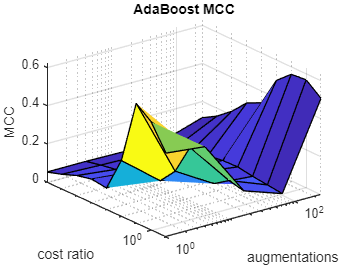

figure
surf(aug(2:end),cost,MCC(:,2:end))
xlabel('augmentations')
ylabel('cost ratio')
zlabel('MCC')
title('AdaBoost MCC')
set(gca,'xscale','log')
set(gca,'yscale','log')

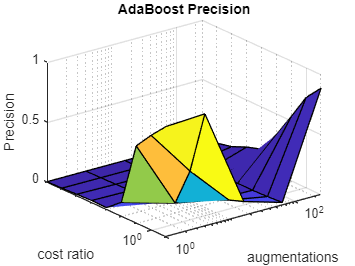


figure
surf(aug(2:end),cost,Precision(:,2:end))
xlabel('augmentations')
ylabel('cost ratio')
zlabel('Precision')
title('AdaBoost Precision')
set(gca,'xscale','log')
set(gca,'yscale','log')

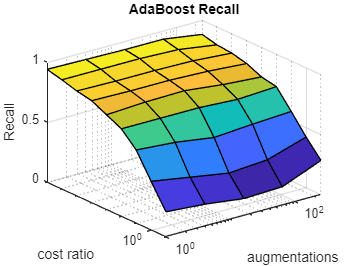


figure
surf(aug(2:end),cost,Recall(:,2:end))
xlabel('augmentations')
ylabel('cost ratio')
zlabel('Recall')
title('AdaBoost Recall')
set(gca,'xscale','log')
set(gca,'yscale','log')

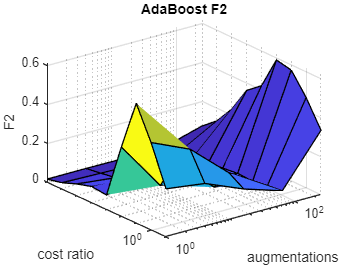


figure
surf(aug(2:end),cost,F2(:,2:end))
xlabel('augmentations')
ylabel('cost ratio')
zlabel('F2')
title('AdaBoost F2')
set(gca,'xscale','log')
set(gca,'yscale','log')

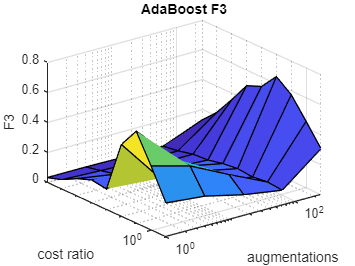


figure
surf(aug(2:end),cost,F3(:,2:end))
xlabel('augmentations')
ylabel('cost ratio')
zlabel('F3')
title('AdaBoost F3')
set(gca,'xscale','log')
set(gca,'yscale','log')

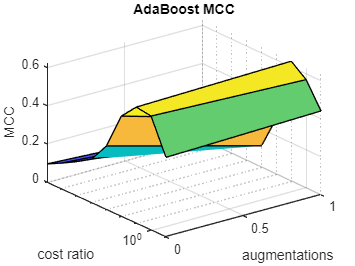

figure
surf(aug(1:2),cost,MCC(:,1:2))
xlabel('augmentations')
ylabel('cost ratio')
zlabel('MCC')
title('AdaBoost MCC')
set(gca,'yscale','log')

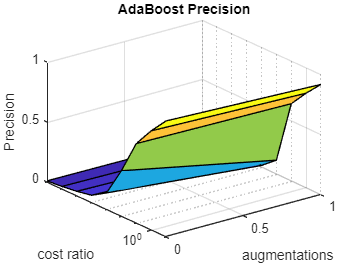


figure
surf(aug(1:2),cost,Precision(:,1:2))
xlabel('augmentations')
ylabel('cost ratio')
zlabel('Precision')
title('AdaBoost Precision')
set(gca,'yscale','log')

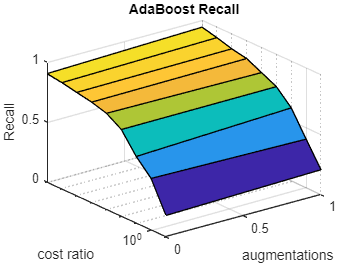


figure
surf(aug(1:2),cost,Recall(:,1:2))
xlabel('augmentations')
ylabel('cost ratio')
zlabel('Recall')
title('AdaBoost Recall')
set(gca,'yscale','log')

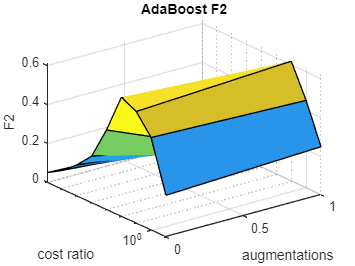


figure
surf(aug(1:2),cost,F2(:,1:2))
xlabel('augmentations')
ylabel('cost ratio')
zlabel('F2')
title('AdaBoost F2')
set(gca,'yscale','log')

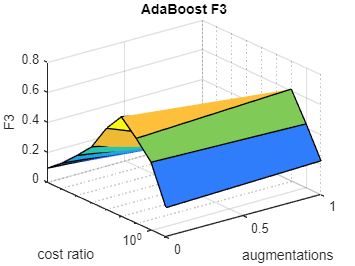


figure
surf(aug(1:2),cost,F3(:,1:2))
xlabel('augmentations')
ylabel('cost ratio')
zlabel('F3')
title('AdaBoost F3')
set(gca,'yscale','log')